# Part 1: Conductance Based Model

The code below implements a basic Connor - Steven Model. 

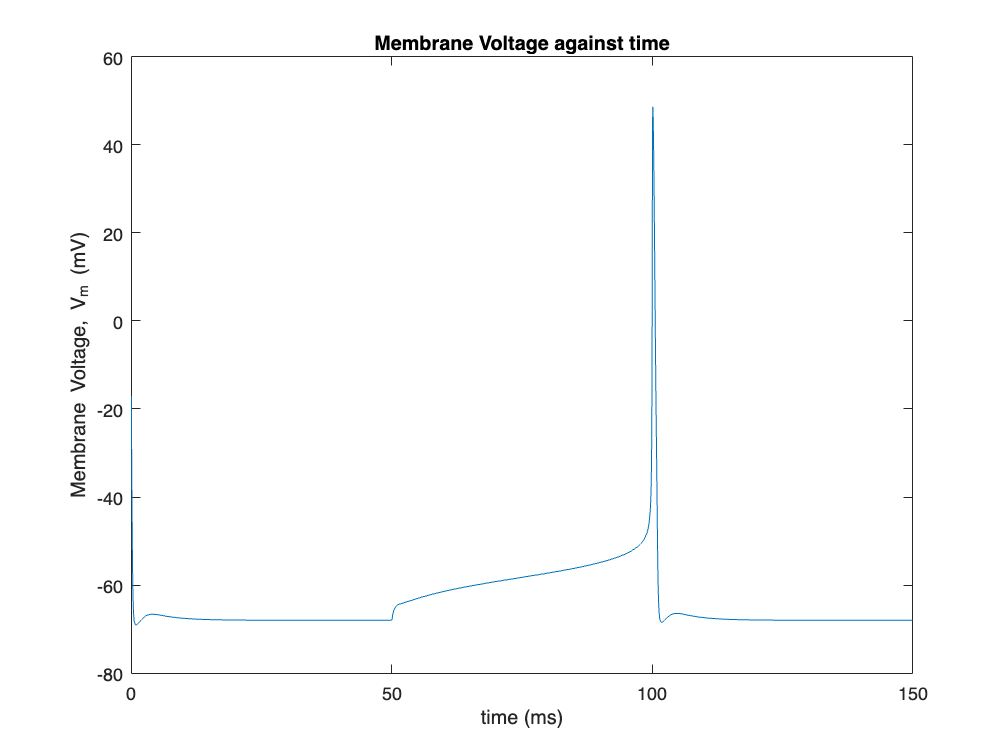

%Define parameters, table 4.3 Theoretical Neuroscience textbook
% the maximum conductance values were slightly modified to change the units from μS to nS

% Channel Conductance
G_leak = 30; %nS 
G_Na_max = 12000; %nS 
G_K_max = 2000; %nS 
G_A_max = 4770; %nS 

% Reversal Potentials
E_Na = 55; %mV 
E_K = -72; %mV 
E_A = -75; %mV
E_leak = -17; %mV

% Membrane Capacitance
C_m = 100; %pF

%define time vector
dt = 0.01; %ms
tmax = 150; %ms
time = 0 : dt : tmax; %ms


% Membrane Voltage (mV)
V_m = zeros(size(time)); 
V_m(1) = E_leak; %initializing membrane voltage

% Applied Current
I_app = zeros(size(time)) ;
change = time > 50 & time < 100;
I_app(change) = 900; %pA

%defining gating variables
m = zeros(size(time));
h = zeros(size(time));
n = zeros(size(time));
a = zeros(size(time));
b = zeros(size(time));


for t = 1 : length(time) - 1
    %computing voltage dependent variables
    %table 4.4 Theoretical Neuroscience textbook
    % slightly modified to acocunt for change in parameters

    % rate constants for Sodium Channel
    alpha_m = (0.38 .*(V_m(t) + 29.7))./(1-exp(-0.1 .* (V_m(t) + 29.7))); 
    beta_m = (15.2) .* (exp(-0.0556 .* (V_m(t) + 54.7)));
    
    alpha_h = 0.266 .* (exp(-0.05 .*(V_m(t) + 48)));
    beta_h = (3.8) ./(1+ exp(-0.1 .*(V_m(t) + 18)));
    
    % rate constants for Potassium Channel
    alpha_n = (0.02 .*(V_m(t)+45.7))./(1-exp(-0.1 .*(V_m(t)+ 45.7)));
    beta_n = 0.25 .* (exp(-0.0125.*(V_m(t)+ 55.7)));

    %rate constants for A Channel
    a_inf = (0.0761 .*(exp(0.0314*(V_m(t)+94.22)))./(1+exp(0.0346 .*(V_m(t)+ 1.17)))).^(1/3);
    tau_a = (0.3632 + 1.158)./(1+exp(0.0497.*(V_m(t)+ 55.96)));
    
    b_inf = ((1)./(1+exp(0.0688*(V_m(t)+ 53.3)))).^4;
    tau_b = (1.24 + 2.678) ./(1+exp(0.0624.*(V_m(t)+ 53.3)));

    %steady states
    m_ss = alpha_m / (alpha_m + beta_m);
    h_ss = alpha_h / (alpha_h + beta_h);
    n_ss = alpha_n / (alpha_n + beta_n);

    %Initializing first variable of gating variable
        if t == 1 
            m(1) = m_ss;
            h(1) = h_ss;
            n(1) = n_ss;
            a(1) = a_inf;
            b(1) = b_inf;
        end

        %calculating gating variables
        dm = (alpha_m * (1 - m(t)) - (beta_m * m(t)))*dt;
        m(t+1) = m(t) + dm;

        dn = (alpha_n * (1 - n(t)) - (beta_n * n(t)))*dt;
        n(t+1) = n(t) + dn;

        dh = (alpha_h * (1 - h(t)) - (beta_h * h(t)))*dt;
        h(t+1) = h(t) + dh;

        da = ((a_inf - a(t)) ./ tau_a) .* dt ;
        a(t+1)= a(t) + da ;

        db = ((b_inf - b(t)) ./ tau_b) .* dt ;
        b(t+1)= b(t) + db ;

        %Calculating the currents for the various ions
        I_leak = - G_leak * (E_leak - V_m(t));
        I_Na = - G_Na_max .* m(t).^3 * h(t) .* (E_Na - V_m(t));
        I_K = -G_K_max .* n(t).^4 .*(E_K - V_m(t));
        I_A = -G_A_max * a(t).^3 .* b(t) .* (E_A - V_m(t));

        %differential equation of voltage
        dV = ((-I_leak - I_Na -I_K - I_A + I_app(t)) / C_m) * dt;
        V_m(t + 1) = V_m(t) + dV; % mV

end
figure
plot(time, V_m)
xlabel('time (ms)')
ylabel('Membrane Voltage, V_m (mV)')
title('Membrane Voltage against time')

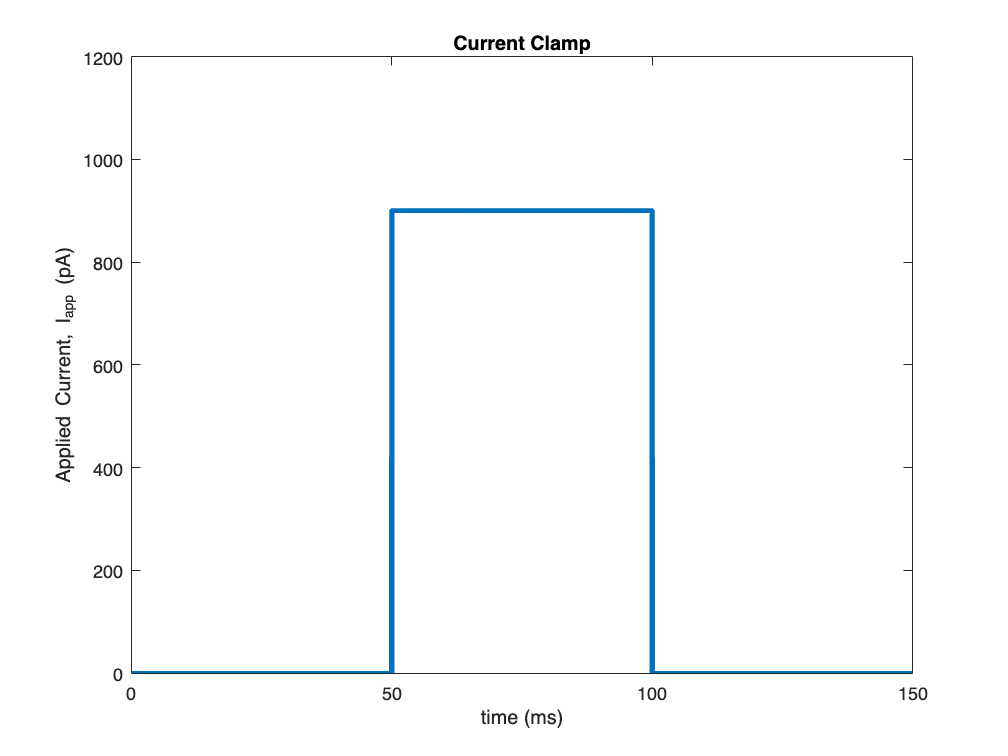


figure
plot(time, I_app, 'Linewidth', 3)
xlabel('time (ms)')
ylabel('Applied Current, I_{app} (pA)')
title('Current Clamp')
ylim([0 1200])

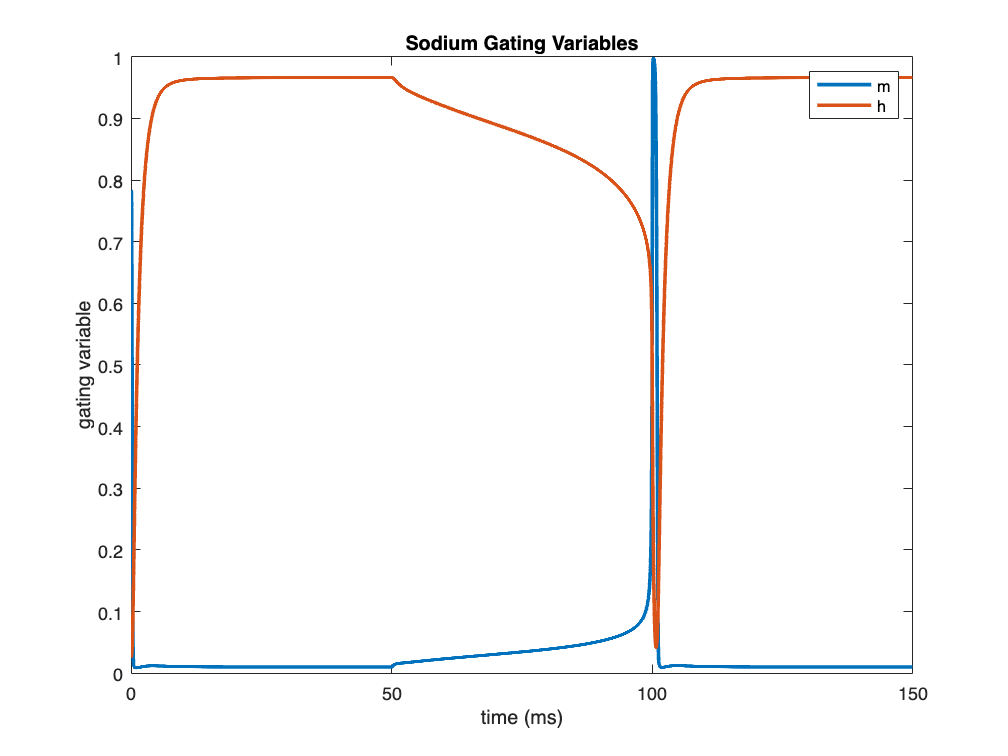


figure
plot(time, m, 'LineWidth', 2)
hold on
plot(time, h, 'LineWidth', 2)
legend('m', 'h')
title('Sodium Gating Variables')
xlabel('time (ms)')
ylabel('gating variable')

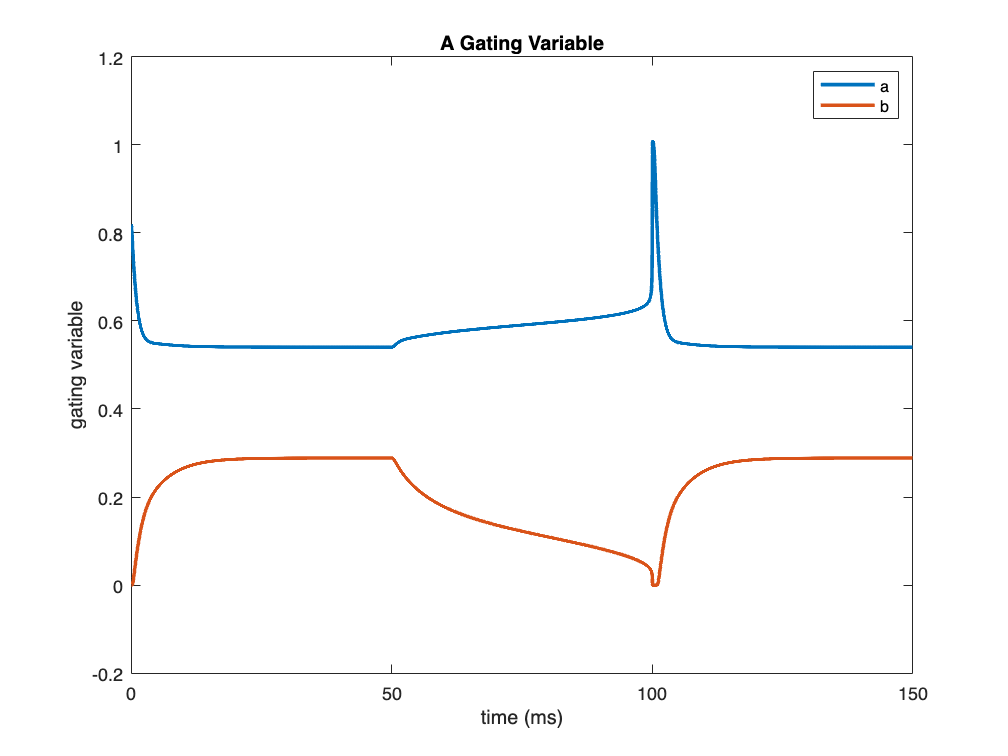


figure
plot(time, a, 'LineWidth', 2)
hold on
plot(time, b, 'LineWidth', 2)
xlabel('time (ms)')
ylabel('gating variable')
title('A Gating Variable')
legend('a', 'b')